load("estimated_parameters.mat")
Vpp = 20;

A1_min = deg2rad(-17);
A1_max = deg2rad(31);
delta_A1 = A1_max - A1_min;


A2_min = deg2rad(-27);
A2_max = deg2rad(27);
delta_A2 = A2_max - A2_min;


Gt0=tf(dc_gain0,[ tau0 1 0])


Gt0 =
 
      -1.448
  --------------
  0.0401 s^2 + s
 
Continuous-time transfer function.
Model Properties


Gt1=tf(dc_gain1,[ tau1 1 0]);

Gt0_min = delta_A1/Vpp;
Gt0_min_db = mag2db(Gt0_min);

Gt1_min = delta_A2/Vpp;
Gt1_min_db = mag2db(Gt1_min);

lowest_Gain = min(Gt0_min,Gt1_min);

mag2db(lowest_Gain)

ans = -27.5582


Gt_limit = tf(lowest_Gain);



omega_range = {0.5,35};
linear_opts = bodeoptions;
linear_opts.MagUnits = "abs";
linear_opts.FreqScale =  'linear';

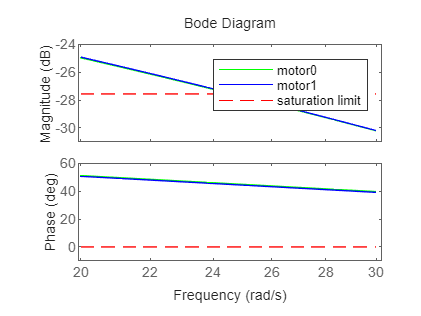

opts = bodeoptions;
opts.MagUnits = "dB";
% opts.FreqScale = "linear";
% opts.PhaseVisible = "off";
figure
bodeplot(Gt0,"g",Gt1,"b",Gt_limit, '--r',{20,30},opts)
legend(["motor0","motor1","saturation limit"])


bw = 24.5

bw = 24.5000


[C_pd0cont,info] = pidtune(Gt0,'PD',bw)


C_pd0cont =
 
             
  Kp + Kd * s
             

  with Kp = -23, Kd = -0.242
 
Continuous-time PD controller in parallel form.
Model Properties


info = struct with fields:
                Stable: 1
    CrossoverFrequency: 24.5000
           PhaseMargin: 60.0000


% sisotool(Gt0,C_pd0cont)



We can see how the bode plot goes below the saturation limit at 24.5rad/s. This is a candidate for a bandwidth of the feedback loop.

Motor 0

opts = pidtuneOptions('PhaseMargin',70,'DesignFocus','reference-tracking');
Gt0d = c2d(Gt0,1/500);
[C_pd0,info] = pidtune(Gt0d,'PD',bw,opts)


C_pd0 =
 
              z-1 
  Kp + Kd * ------
              Ts  

  with Kp = -21.6, Kd = -0.423, Ts = 0.002
 
Sample time: 0.002 seconds
Discrete-time PD controller in parallel form.
Model Properties


info = struct with fields:
                Stable: 1
    CrossoverFrequency: 24.5000
           PhaseMargin: 70.0000




Ld0=C_pd0*Gt0d;
T_pd0 = feedback(Ld0,1);
S_pd0 = 1/(1+Ld0)


S_pd0 =
 
    z^2 - 1.951 z + 0.9513
  ---------------------------
  1.015 z^2 - 1.95 z + 0.9381
 
Sample time: 0.002 seconds
Discrete-time transfer function.
Model Properties


Si_pd0 = Gt0d/(1+Ld0)


Si_pd0 =
 
  -7.103e-05 z^3 + 6.874e-05 z^2 + 6.874e-05 z - 6.646e-05
  --------------------------------------------------------
    1.015 z^4 - 3.931 z^3 + 5.709 z^2 - 3.686 z + 0.8924
 
Sample time: 0.002 seconds
Discrete-time transfer function.
Model Properties


So_pd0 = C_pd0/(1+Ld0)


So_pd0 =
 
  -211.5 z^3 + 602.7 z^2 - 571.9 z + 180.7
  ----------------------------------------
        1.015 z^2 - 1.95 z + 0.9381
 
Sample time: 0.002 seconds
Discrete-time transfer function.
Model Properties


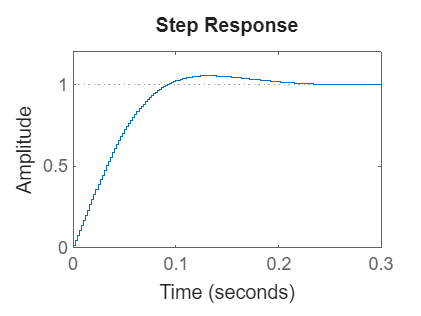

step(T_pd0);

stepinfo(T_pd0)

ans = struct with fields:
         RiseTime: 0.0660
    TransientTime: 0.1960
     SettlingTime: 0.1940
      SettlingMin: 0.9077
      SettlingMax: 1.0540
        Overshoot: 5.3983
       Undershoot: 0
             Peak: 1.0540
         PeakTime: 0.1320


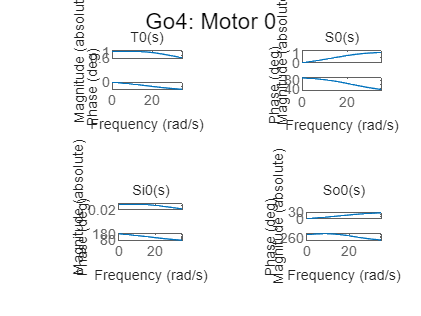

figure
subplot(2,2,1)
sgtitle("Go4: Motor 0")
bodeplot(T_pd0,omega_range,linear_opts)
title("T0(s)")

subplot(2,2,2)
bodeplot(S_pd0,omega_range,linear_opts)
title("S0(s)")

subplot(2,2,3)
bodeplot(Si_pd0,omega_range,linear_opts)
title("Si0(s)")

subplot(2,2,4)
bodeplot(So_pd0,omega_range,linear_opts)
title("So0(s)")

Motor 1

opts = pidtuneOptions('PhaseMargin',70,'DesignFocus','reference-tracking');
Gt1d = c2d(Gt1,1/500);
[C_pd1,info1] = pidtune(Gt1d,'PD',bw,opts)


C_pd1 =
 
              z-1 
  Kp + Kd * ------
              Ts  

  with Kp = -21.4, Kd = -0.43, Ts = 0.002
 
Sample time: 0.002 seconds
Discrete-time PD controller in parallel form.
Model Properties


info1 = struct with fields:
                Stable: 1
    CrossoverFrequency: 24.5000
           PhaseMargin: 70.0000




Ld1=C_pd1*Gt1d;
T_pd1 = feedback(Ld1,1);
S_pd1 = 1/(1+Ld1)


S_pd1 =
 
     z^2 - 1.952 z + 0.9523
  ----------------------------
  1.015 z^2 - 1.951 z + 0.9388
 
Sample time: 0.002 seconds
Discrete-time transfer function.
Model Properties


Si_pd1 = Gt1d/(1+Ld1)


Si_pd1 =
 
  -7.065e-05 z^3 + 6.842e-05 z^2 + 6.842e-05 z - 6.619e-05
  --------------------------------------------------------
    1.015 z^4 - 3.933 z^3 + 5.714 z^2 - 3.691 z + 0.894
 
Sample time: 0.002 seconds
Discrete-time transfer function.
Model Properties


So_pd1 = C_pd1/(1+Ld1)


So_pd1 =
 
  -214.9 z^3 + 613.1 z^2 - 582.4 z + 184.3
  ----------------------------------------
        1.015 z^2 - 1.951 z + 0.9388
 
Sample time: 0.002 seconds
Discrete-time transfer function.
Model Properties


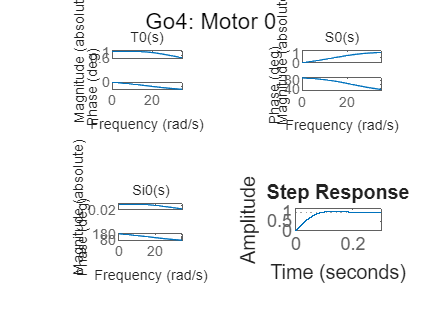

step(T_pd1);

stepinfo(T_pd1)

ans = struct with fields:
         RiseTime: 0.0660
    TransientTime: 0.1960
     SettlingTime: 0.1960
      SettlingMin: 0.9081
      SettlingMax: 1.0548
        Overshoot: 5.4810
       Undershoot: 0
             Peak: 1.0548
         PeakTime: 0.1320


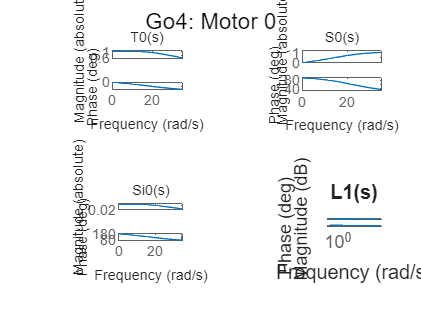

bode(Ld1,omega_range)
title("L1(s)")

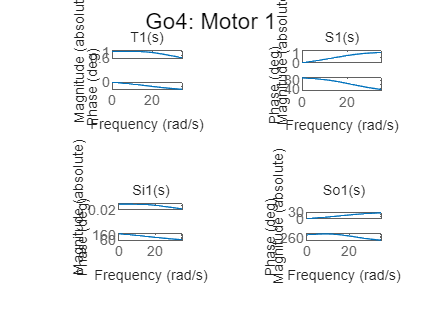


figure
subplot(2,2,1)
sgtitle("Go4: Motor 1")
bodeplot(T_pd1,omega_range,linear_opts)
title("T1(s)")

subplot(2,2,2)
bodeplot(S_pd1,omega_range,linear_opts)
title("S1(s)")

subplot(2,2,3)
bodeplot(Si_pd1,omega_range,linear_opts)
title("Si1(s)")

subplot(2,2,4)
bodeplot(So_pd1,omega_range,linear_opts)
title("So1(s)")

% opts = pidtuneOptions('PhaseMargin',90,'DesignFocus','reference-tracking');
% 
% Gt0_star = Gt0 * tf([1],[1 0])
% Gt0d_star = c2d(Gt0_star,1/500);
% [C_pd0_star,info] = pidtune(Gt0d,'PD',26.0,opts)
% 
% T_pd_star = feedback(C_pd0_star*Gt0d_star,-1);
% step(T_pd);
% Ld_star=C_pd0_star*Gt0d_star;
% bode(Gt0_star);
% title("G*(s)")
% nyqplot(Gt0_star)
% title("G*(s)")
% 
% bode(Ld_star)
% title("L*(s)")
% nyqplot(Ld_star)
% title("L*(s)")
% 
% 
% bode(T_pd_star)
% title("T*(s)")
% nyqplot(T_pd_star)
% title("T*(s)")

